# **Pandemic Simulation**

clear; clc; close all;

## Parameters

n_agents = 100;
starting_infection_rate = 0.01;  risk_of_infection = 0.1

risk_of_infection = 0.0500

infection_radius = 0.3

infection_radius = 0.3000

quarantine_prob = 0.7

quarantine_prob = 0.7000

live_visualisation = true

live_visualisation = logical
   1


## Simulation

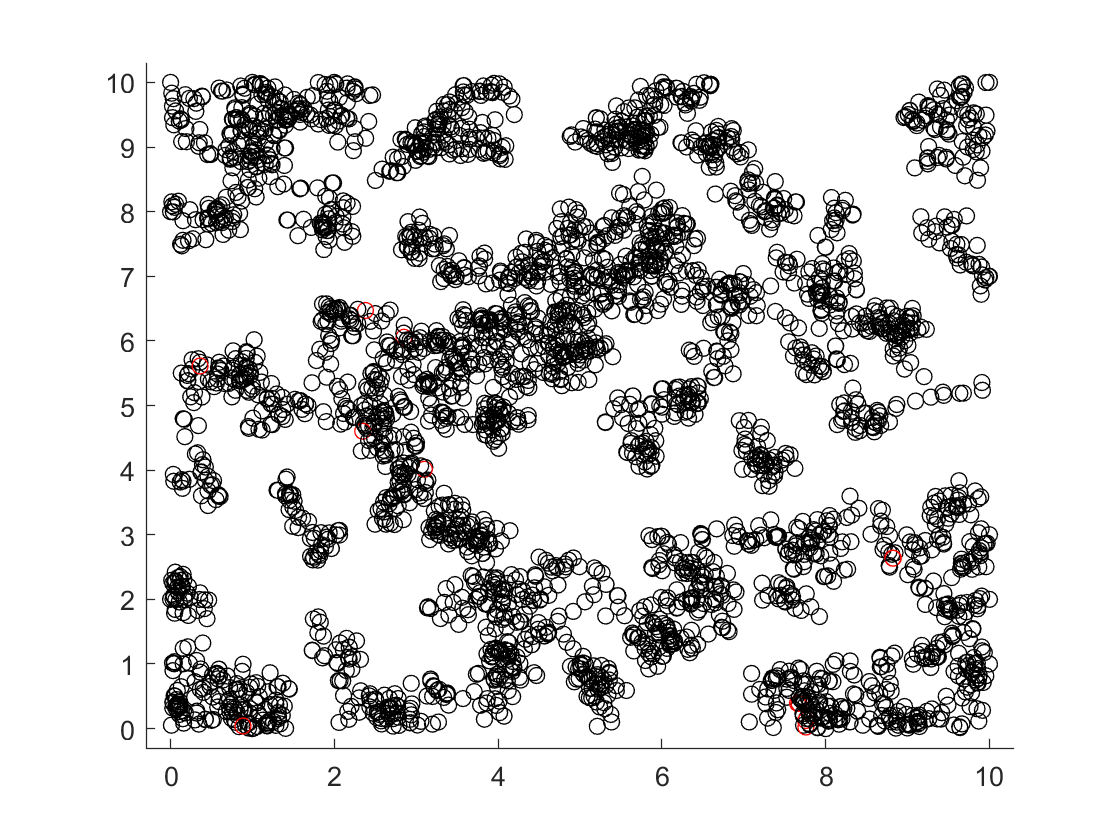

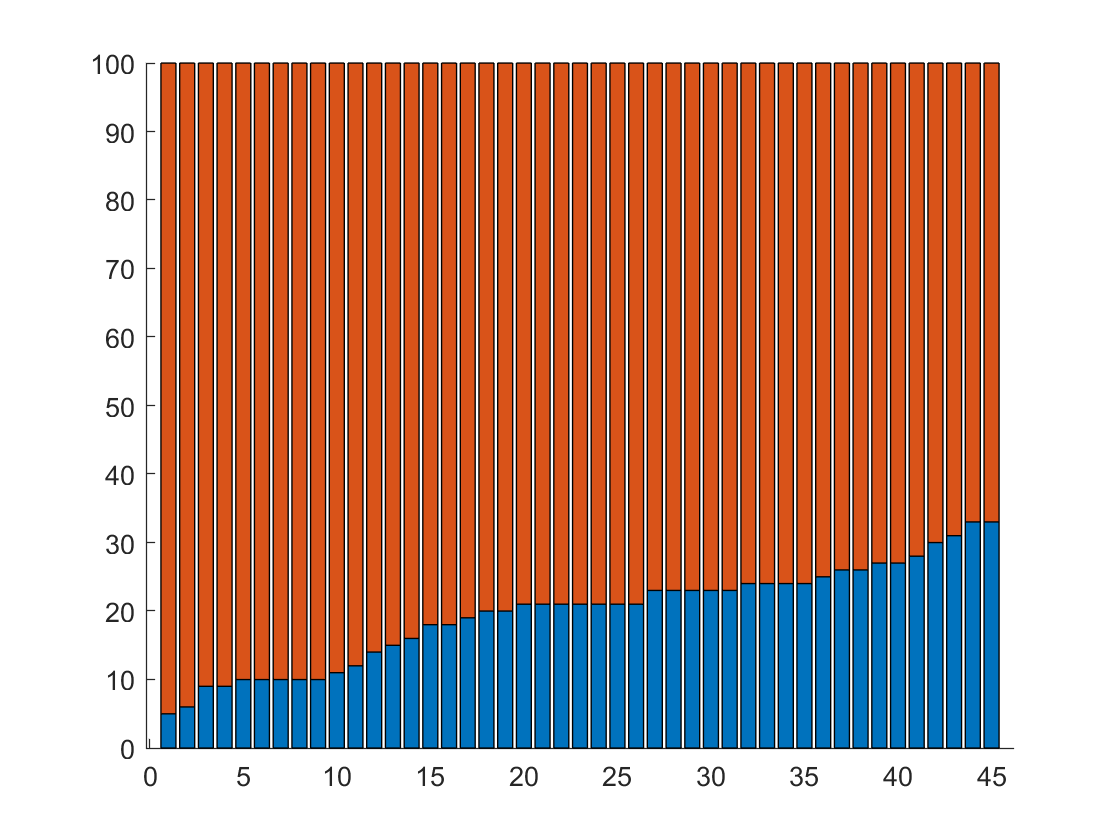

Error using matlab.graphics.axis.Axes/get
Operation terminated by the user.

Error in matlab.graphics.chart.primitive.bar.internal.updateTicks (line 6)
yTickData = get(hAx,yTickString);

Error in 

%% Initialising agents with random positions in max_xy square
max_xy = 10;
agents = agent.empty(0,0);
for i = n_agents:-1:1
    agents(i).position = randi([0,max_xy],[2,1]);
end

%% Infection
starting_n_infected_agents = starting_infection_rate * n_agents;
infections = 1;
while infections <= starting_n_infected_agents
    index = randi([1,n_agents]);
    if agents(index).infected == 0 %not infected yet
        agents(index).infected = 1;
        infections = infections + 1;
    end
end

%% Quarantine
quarantine_pos = [100;100]; %position for quarantine area

 
%% Simulation
timestep = 0.1;
vel_scaling = 3;
steps = 200;
step = 0;
n_infected_agents = starting_n_infected_agents;
infection_data = [];

%%Initialise visualisation figure
if live_visualisation == 1
    figure(1)
    xlim([-0.3,max_xy + 0.3])
    ylim([-0.3,max_xy + 0.3])
end

%%Simulation
while step <= steps
    %Moving
    for i = 1:n_agents
        if agents(i).quarantine == 0 %only move agents which are not in quarantine
            direction = randi(360);
            vel = rand() * vel_scaling;
            move = agents(i).position + timestep * vel * [cosd(direction);sind(direction)]; %new position after move
            %check whether new position is in square
            if (move(1) < 0 || move(1) > 10) || (move(2) < 0 || move(2) > 10)
                %outside square:
                move = agents(i).position; %don't perform move and generate new step in next timestep
            end
            agents(i).position = move;
        end
    end

    %Infection?
    for i = 1:n_agents %Iterating over every agent
        if agents(i).infected == 0 %only if not infected yet
            for j = 1:n_agents  %Iterating over every agent 
                if j ~=i  && agents(j).quarantine == 0  %except the "active one" (j~=i) & the ones in qurantine
                    if abs(agents(i).position - agents(j).position) < infection_radius %in critical radius?
                        if (rand() < risk_of_infection)     %infection?
                            agents(i).infected = 1;
                            n_infected_agents = n_infected_agents + 1;
                            if (rand() < quarantine_prob)    %quarantine?
                                agents(i).quarantine = 1;
                                agents(i).position = quarantine_pos;
                            end
                        end
                    end
                end
            end
        else %agent already infected
            if (rand() <= quarantine_prob && agents(i).quarantine ~=1)    %quarantine?
                agents(i).quarantine = 1;
                agents(i).position = quarantine_pos;
            end

        end

    end
    
    %Plot of agents
    if live_visualisation == 1
        figure(1)
        hold on
        for i = 1:n_agents
            if agents(i).infected == 1
                plot(agents(i).position(1), agents(i).position(2),'ro')
            else
                plot(agents(i).position(1), agents(i).position(2),'ko')
            end
        end
        xlim([-0.3,max_xy + 0.3])
        ylim([-0.3,max_xy + 0.3])
        hold off
    end

    %Plot for analytics
    infection_data = [infection_data; n_infected_agents n_agents-n_infected_agents];
    if live_visualisation == 1
        figure(2)
        bar(infection_data,'stacked');
        legend('infected','healthy');
        pause(0.1);
    end
    

    %Increase simulation step
    step = step + 1;
    %Pause

end


if live_visualisation ~= 1
    figure(2)
    bar(infection_data,'stacked');
    legend('infected','healthy');
end
